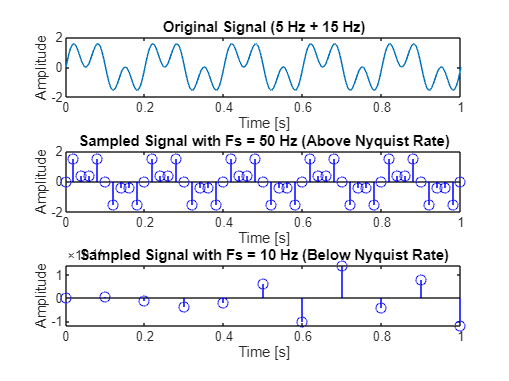

% Parameters
Fs1 = 50;  % Sampling frequency 1 (above Nyquist rate)
Fs2 = 10;  % Sampling frequency 2 (below Nyquist rate)
t = linspace(0, 1, 1000);  % Time vector
f1 = 5;   % Signal frequency 1
f2 = 15;  % Signal frequency 2

% Original signal
x = sin(2 * pi * f1 * t) + sin(2 * pi * f2 * t);

% Sampling the signal
t1 = 0:1/Fs1:1;
x1 = sin(2 * pi * f1 * t1) + sin(2 * pi * f2 * t1);

t2 = 0:1/Fs2:1;
x2 = sin(2 * pi * f1 * t2) + sin(2 * pi * f2 * t2);

% Plotting
figure;

% Original signal
subplot(3, 1, 1);
plot(t, x);
title('Original Signal (5 Hz + 15 Hz)');
xlabel('Time [s]');
ylabel('Amplitude');

% Sampled signal with Fs1
subplot(3, 1, 2);
stem(t1, x1, 'b');
title(['Sampled Signal with Fs = ', num2str(Fs1), ' Hz (Above Nyquist Rate)']);
xlabel('Time [s]');
ylabel('Amplitude');

% Sampled signal with Fs2
subplot(3, 1, 3);
stem(t2, x2, 'b');
title(['Sampled Signal with Fs = ', num2str(Fs2), ' Hz (Below Nyquist Rate)']);
xlabel('Time [s]');
ylabel('Amplitude');